# TP 4 : Simulation d'un système continu

clear;clc;close;

% Temps de simulation
t = 120; % secondes

m = 1; % kg
k = 20; % Newton/m
R = 100e-3; % Ns/m

fs = 10e3; % Hz
Ts = 1/fs; % = 100e-6; % secondes
count = ceil(t/Ts)

count = 1200000


% F0, une force de 100 N appliquée pendant 1 ms
F0 = (ones(10, 1)*100);

A = [1, Ts;
    (-k*Ts/m), (1-R*Ts/m)];
B = [0;
    (Ts/m)];
C = [1, 0;
    0, 3.6];
D = [0;
    0];

% Vecteurs
out = zeros(2, count); % Vecteur de sortie
vectE = [0; 0]; % Condition initiale : x = 0 et v = 0

for n=1:count
    F0_val = 0; % Plus d'entrée
    if (length(F0) >= n)
        F0_val = F0(n); % Entrée présente
    end

    [out(:,n), vectE] = iteration(A,B,C,D,F0_val,vectE);
end


## Plot

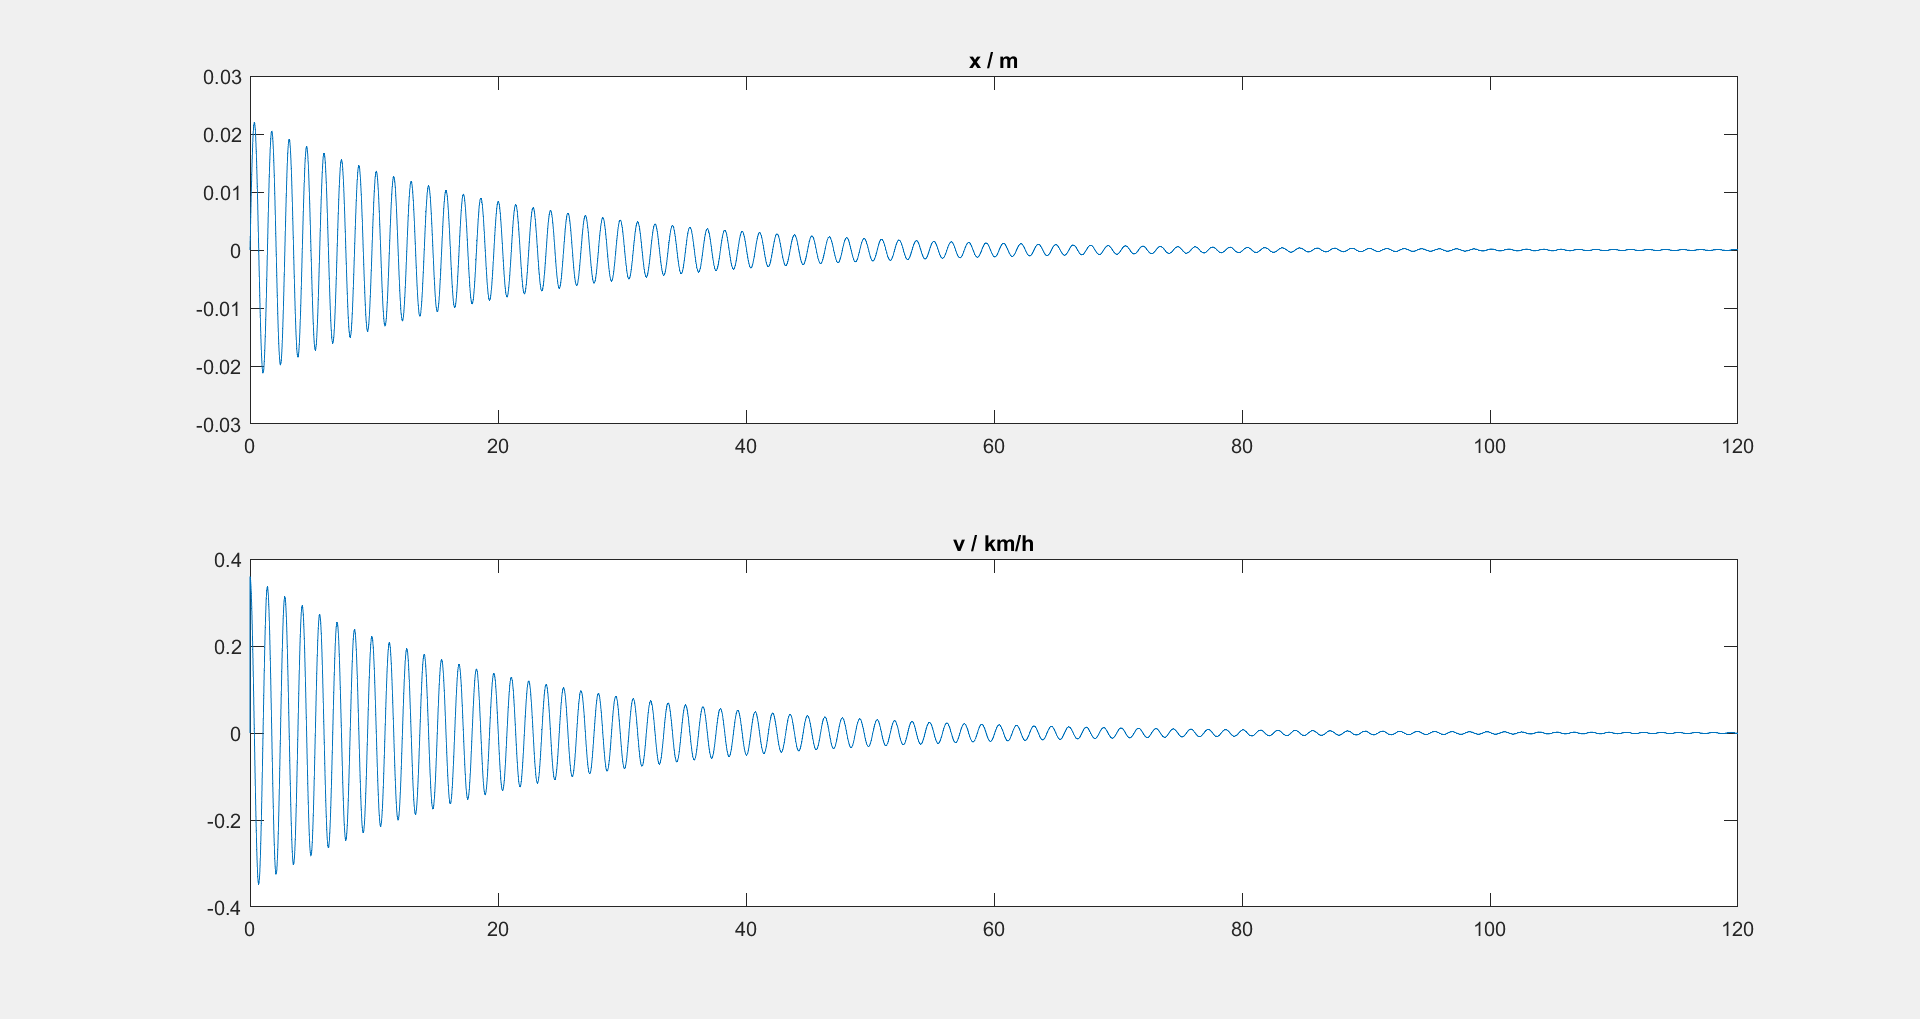

close;

x_out = out(1, :);
v_out = out(2, :);
time = 0:Ts:(t-Ts);

figure("WindowState","maximized"); % Ouvrir la fenêtre en maximized
set(gcf,'Visible','on'); % Ouvre le plot automatiquement (en live script)

subplot(211);
plot(time, x_out);
title("x / m");
subplot(212);
plot(time, v_out);
title("v / km/h");

% subplot(313);
% plot(time, x_out); hold on;
% plot(time, v_out);
% title("Système entier");
% legend("x", "v");



## 3.2 Eigenvalues

% Valeures propres de A :
poles = eig(A)

poles =    1.0000 + 0.0004i
   1.0000 - 0.0004i


amortissements = num2str(abs(poles), 100)

amortissements = 2×50 char array
    '0.999995099987994962020820821635425090789794921875'
    '0.999995099987994962020820821635425090789794921875'


oscillations = num2str(angle(poles), 10)

oscillations = 2×16 char array
    ' 0.0004471878499'
    '-0.0004471878499'
